# Montolio Paper ODEs

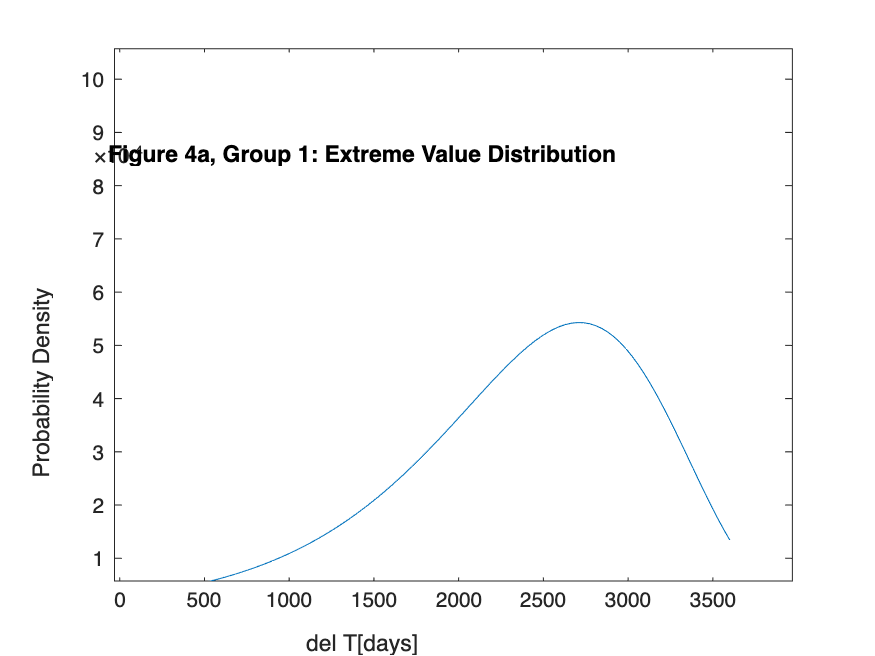

clc;
clear;
scenario = "4a";

%%Test how changing parameters k-values affect figures

%This model is made up of 3 ODEs. They represent healthy axons(A), damaged
%axons(Ad) and the process of axonal degeneration(D).

%Time Range(days)
tinitial=0;
tfinal=3600;
numberOfTimes = 101;
t=linspace(tinitial, tfinal, numberOfTimes);

%Figure 4
if strcmp(scenario,"4a")
    group=1;
    y=AR(t,group);
    figure()
    plot(t,y)
    xlabel("del T[days]")
    ylabel("Probability Density")
    title("Figure 4a, Group 1: Extreme Value Distribution")

    axis([0 4000 0 10E-4])


elseif strcmp(scenario,"4b")
    group=2;
    y=AR(t,group);
    figure()
    plot(t,y)
    xlabel("del T[days]")
    ylabel("Probability Density")
    title("Figure 4b, Group 2: Weibull Distribution")
    axis([0 4000 0 10E-4])
elseif strcmp(scenario,"4c")
    group=3;
    y=AR(t,group);
    figure()
    plot(t,y)
    xlabel("del T[days]")
    ylabel("Probability Density")
    title("Figure 4c, Group 3: Rayleigh Distribution")
    axis([0 4000 0 10E-4])
end



%Figure 6-peripapillary
if strcmp(scenario,"6a")
    group=1;
    section=1;
    %Initial conditions, baseline is completely healthy axons(Ad=0, D=0)
    Ci=[84 0 0];
    soln=ode45(@(t,Ci)ODEs(t,Ci,group),t,Ci);
    A=deval(soln,t,1);
    Ad=deval(soln,t,2);
    D=deval(soln,t,3);
    At=A+Ad;

    if t(1)
        At=A(0);
    end

    figure
    plot(t,A,'r')
    xlabel('t[days]')
    ylabel('Thickness[um]')
    title('Figure 6a: Group 1')
    hold on
    plot(t,Ad,'Color',[0.9290 0.6940 0.1250])
    plot(t,D,'Color',[0.5 0 0.8])
    plot(t,At,'b')
    legend('A', '{Ad}', 'D','{At}')
    axis([0 4000 0 90])
    hold off

elseif strcmp(scenario,"6b")
    %Initial conditions, baseline is completely healthy axons(Ad=0, D=0)
    group=2;
    Ci=[89 0 0];
    soln=ode45(@(t,Ci)ODEs(t,Ci,group),t,Ci);
    A=deval(soln,t,1);
    Ad=deval(soln,t,2);
    D=deval(soln,t,3);
    At=A+Ad;

    if t(1)
        At=A(0);
    end

    figure
    plot(t,A,'r')
    xlabel('t[days]')
    ylabel('Thickness[um]')
    title('Figure 6b: Group 2')
    hold on
    plot(t,Ad,'Color',[0.9290 0.6940 0.1250])
    plot(t,D,'Color',[0.5 0 0.8])
    plot(t,At,'b')
    legend('A', '{Ad}', 'D','{At}')
    axis([0 4000 0 90])
    hold off

elseif strcmp(scenario,"6c")
    %Initial conditions, baseline is completely healthy axons(Ad=0, D=0)
    group=3;
    Ci=[100.5 0 0];
    soln=ode45(@(t,Ci)ODEs(t,Ci,group),t,Ci);
    A=deval(soln,t,1);
    Ad=deval(soln,t,2);
    D=deval(soln,t,3);
    At=A+Ad;

    if t(1)
        At=A(0);
    end
    
    figure
    plot(t,A,'r')
    xlabel('t[days]')
    ylabel('Thickness[um]')
    title('Figure 6c: Group 3')
    hold on
    plot(t,Ad,'Color',[0.9290 0.6940 0.1250])
    plot(t,D,'Color',[0.5 0 0.8])
    plot(t,At,'b')
    legend('A', '{Ad}', 'D','{At}')
    axis([0 4000 0 100])
    hold off
end 

%Using superior k parameters
if strcmp(scenario,"6aS")
    %Initial conditions, baseline is completely healthy axons(Ad=0, D=0)
    group=4;
    Ci=[84 0 0];
    soln=ode45(@(t,Ci)ODEs(t,Ci,group),t,Ci);
    A=deval(soln,t,1);
    Ad=deval(soln,t,2);
    D=deval(soln,t,3);
    At=A+Ad;

    if t(1)
        At=A(0);
    end

    figure
    plot(t,A,'r')
    xlabel('t[days]')
    ylabel('Thickness[um]')
    title('Figure 6aS: Group 1')
    hold on
    plot(t,Ad,'Color',[0.9290 0.6940 0.1250])
    plot(t,D,'Color',[0.5 0 0.8])
    plot(t,At,'b')
    legend('A', '{Ad}', 'D','{At}')
    hold off

elseif strcmp(scenario,"6bS")
    %Initial conditions, baseline is completely healthy axons(Ad=0, D=0)
    group=5;
    Ci=[89 0 0];
    soln=ode45(@(t,Ci)ODEs(t,Ci,group),t,Ci);
    A=deval(soln,t,1);
    Ad=deval(soln,t,2);
    D=deval(soln,t,3);
    At=A+Ad;

    if t(1)
        At=A(0);
    end

    figure
    plot(t,A,'r')
    xlabel('t[days]')
    ylabel('Thickness[um]')
    title('Figure 6bS: Group 2')
    hold on
    plot(t,Ad,'Color',[0.9290 0.6940 0.1250])
    plot(t,D,'Color',[0.5 0 0.8])
    plot(t,At,'b')
    legend('A', '{Ad}', 'D','{At}')
    hold off

elseif strcmp(scenario,"6cS")
    %Initial conditions, baseline is completely healthy axons(Ad=0, D=0)
    group=6;
    Ci=[100.5 0 0];
    soln=ode45(@(t,Ci)ODEs(t,Ci,group),t,Ci);
    A=deval(soln,t,1);
    Ad=deval(soln,t,2);
    D=deval(soln,t,3);
    At=A+Ad;

    if t(1)
        At=A(0);
    end

    figure
    plot(t,A,'r')
    xlabel('t[days]')
    ylabel('Thickness[um]')
    title('Figure 6cS: Group 3')
    hold on
    plot(t,Ad,'Color',[0.9290 0.6940 0.1250])
    plot(t,D,'Color',[0.5 0 0.8])
    plot(t,At,'b')
    legend('A', '{Ad}', 'D','{At}')
    hold off
end
%add inferior, nasal and temporal 



function derivVector=ODEs(t,y,group)
%Parameters
%Constants are kinf, kreg, kdegA, kdegAd which vary for each group
if group==1
    % Using peripapillary values for Group 1 from Table 1S, units are [1/day]
    kinf=0.953;
    kreg=8.850E-7;
    kdegA=3.372E-5;
    kdegAd=2.200E-6;

elseif group==2
    % Using peripapillary values for Group 2 from Table 1S, units are [1/day]
    kinf=0.914;
    kreg=1.080E-5;
    kdegA=4.887E-5;
    kdegAd=3.542E-5;

elseif group==3
    % Using peripapillary values for Group 3 from Table 1S, units are [1/day]
    kinf=1.440;
    kreg=1.400E-5;
    kdegA=1.068E-4;
    kdegAd=1.476E-5;
end

if group==4
    % Using superior values for Group 1 from Table 1S, units are [1/day]
    kinf=0.997;
    kreg=3.597E-7;
    kdegA=3.308E-5;
    kdegAd=4.84E-6;

elseif group==5
    % Using superior values for Group 1 from Table 1S, units are [1/day]
    kinf=0.874;
    kreg=2.440E-6;
    kdegA=3.546E-5;
    kdegAd=4.946E-5;

elseif group==6
    % Using superior values for Group 1 from Table 1S, units are [1/day]
    kinf=1.695;
    kreg=1.320E-6;
    kdegA=5.356E-5;
    kdegAd=6.776E-5;
end 

A=y(1);
Ad=y(2);
D=y(3);

dA_dt= -kinf*AR(t,group)*A+kreg*Ad-kdegA*A;
dAd_dt= kinf*AR(t,group)*A-kreg*Ad-kdegAd*Ad;
dD_dt=kdegA*A+kdegAd*Ad;

derivVector = [dA_dt, dAd_dt, dD_dt]';
end

%AR(t) is the autoimmune response, which varies for groups 1-3
%For group 1, AR(t) uses an extreme value distribution
function y=AR(t,group)
if group==1
    mu=2711.8;
    sigma=677.7;
    y=(sigma.^-1).*(exp((t-mu)./sigma)).*exp(-exp((t-mu)/sigma));

%For group 2, AR(t) uses a Weibull distribution
elseif group==2
    b=3.2;
    a=1947.2;
    y=(b/a).*((t/a).^(b-1)).*(exp(-(t/a).^b));

%For group 3, AR(t) uses a Rayleigh distribution
elseif group==3
    sigma=818.7;
    y=(t/(sigma.^2)).*(exp((-t.^2)/(2*(sigma.^2))));
end
end


